# PID controller - Active Suspension System

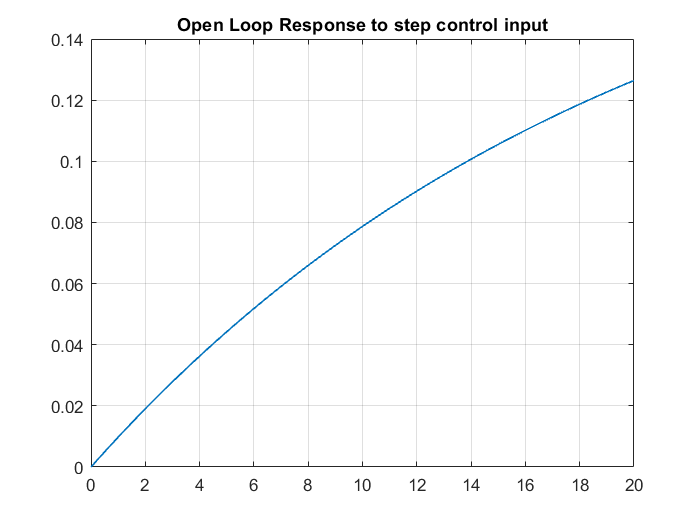

close all;
% JJRATH- Feb2021
% Reference Scaling Design Task
%--------------------------
%----------------------------
% Ex:  Active Cruise Control
% Automatic cruise control is an excellent example of a feedback control 
% system found in many modern vehicles. The purpose of the cruise control system is 
% to maintain a constant vehicle speed despite external disturbances, such as changes in 
% wind or road grade. This is accomplished by measuring the vehicle speed,
% comparing it to the desired or reference speed, and automatically adjusting the
% throttle according to a control law.


% A simple model of the cruise control problem 
m = 1000;
b = 50;
r = 10;

A = -b/m;
B = 1/m;
C = 1;
D = 0;

%--- Develop State Space Model
states = {'velocity (m/s)'};
inputs = {'u_th'}; % Throttle Input
outputs  = {'Velocity'};
cruise_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

%--- The TF model
s = tf('s');
P_cruise = 1/(m*s+b);
%-- Design Requirements
% The car will reach a maximum velocity of 10 m/s (22 mph), 
% An automobile should be able to accelerate up to that speed in less than 5 seconds

% STEP 1: Open Loop Response
Ref = 10; t = 0:0.1:20;
[Y_ol,t,Xol] = step(Ref*P_cruise,t); 
figure;
plot(t,Y_ol,'LineWidth',1);
title('Open Loop Response to step control input'); grid on;

## P Controller Design

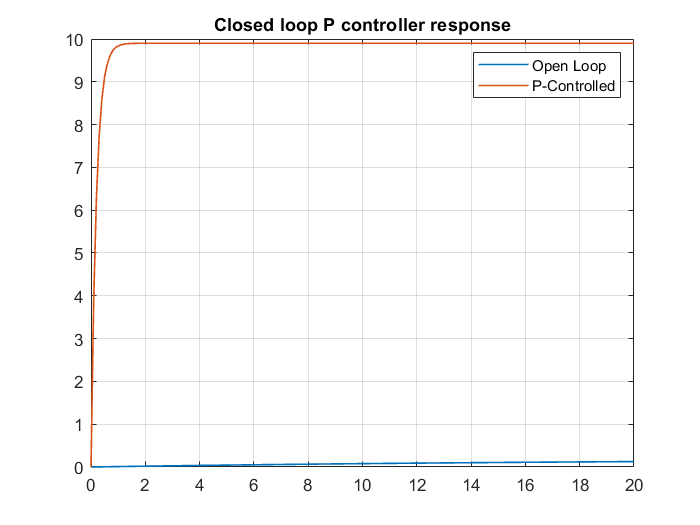

% Lets assume a value of Kp
Kp = 5000; Kd = 0; Ki = 0;   %% Try upto 5000
ConP = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
P = feedback(ConP*P_cruise,1);% feedback command places the controller structure.
%-- Simulate the closed loop system
[Yc_p,t,Xc_p]=step(P*Ref,t); % Simulating closed loop response
%--- Plot the response for P controller
figure;
plot(t,Y_ol,'LineWidth',1); hold on;plot(t,Yc_p,'LineWidth',1);
title('Open Loop Response to step control input'); grid on;
legend('Open Loop','P-Controlled'); 
title('Closed loop P controller response')

%----------------------------------------

## Design of a Proportional-Derivative Controller

Lets assume a value of Kp and Kd

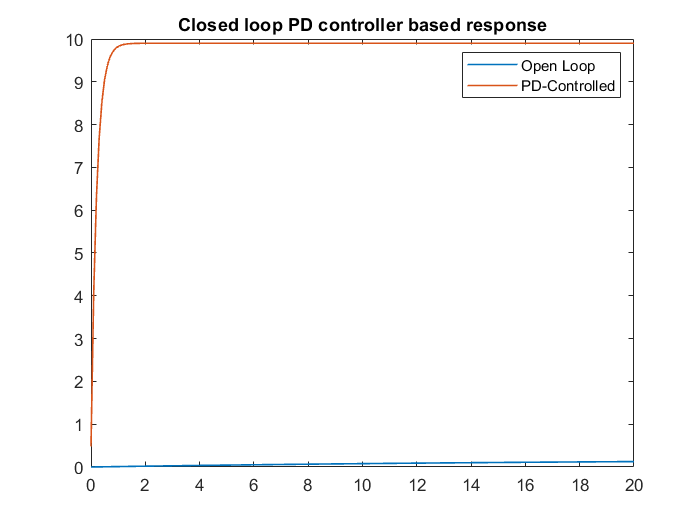

Kp = 5000; Kd = 50; Ki = 0;
ConPD = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
PD = feedback(ConPD*P_cruise,1);% feedback command places the controller structure.
%-- Simulate the closed loop system
[Yc_pd,t,Xc_pd]=step(PD*Ref,t); % Simulating closed loop response
%--- Plot the response for P controller
figure;
plot(t,Y_ol,'LineWidth',1); hold on;plot(t,Yc_pd,'LineWidth',1);
legend('Open Loop','PD-Controlled'); 
title('Closed loop PD controller based response');

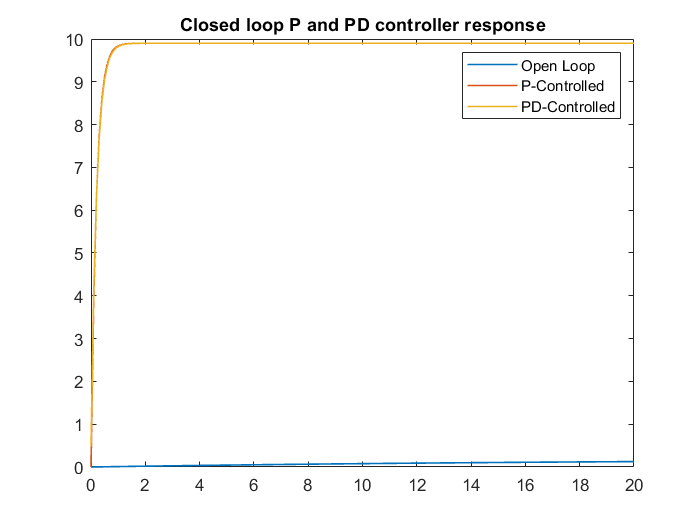

%-- P and PD Controller Response Comparsions
figure;
plot(t,Y_ol,'LineWidth',1); hold on;plot(t,Yc_p,'LineWidth',1);plot(t,Yc_pd,'LineWidth',1);
legend('Open Loop','P-Controlled','PD-Controlled'); 
title('Closed loop P and PD controller response');

## Design of a Proportional-Integral Controller

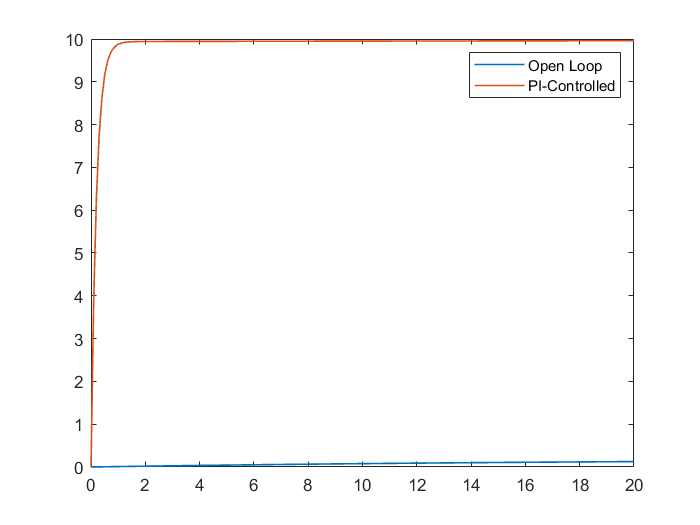

% Lets assume a value of Kp and Kd
Kp = 5000; Kd = 0; Ki =100;
ConPI = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
PI = feedback(ConPI*P_cruise,1);% feedback command places the controller structure.
%----------------------
%-- Simulate the closed loop system
[Yc_pi,t,Xc_pi]=step(PI*Ref,t); % Simulating closed loop response
%--- 
figure;
plot(t,Y_ol,'LineWidth',1); hold on;plot(t,Yc_pi,'LineWidth',1);
legend('Open Loop','PI-Controlled'); 

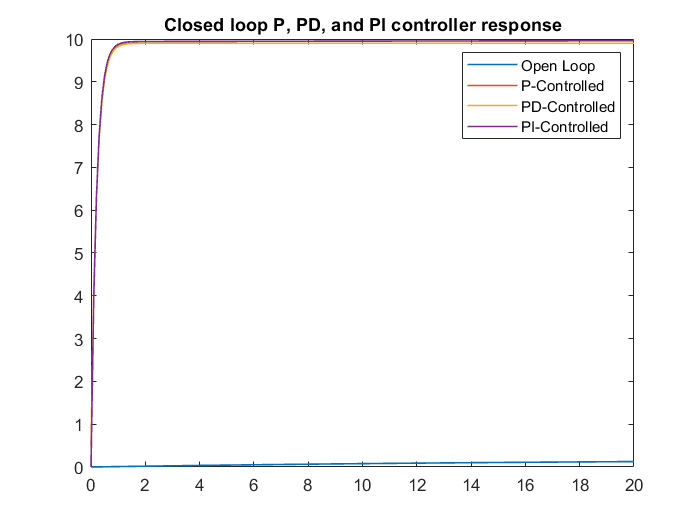

%----- Plot the response for P, PD and PI controller
figure;
plot(t,Y_ol,'LineWidth',1); hold on; plot(t,Yc_p,'LineWidth',1);
plot(t,Yc_pd,'LineWidth',1);plot(t,Yc_pi,'LineWidth',1);
legend('Open Loop','P-Controlled','PD-Controlled','PI-Controlled'); 
title('Closed loop P, PD, and PI controller response');

## Design of a Proportional-Integral-Derivative Controller

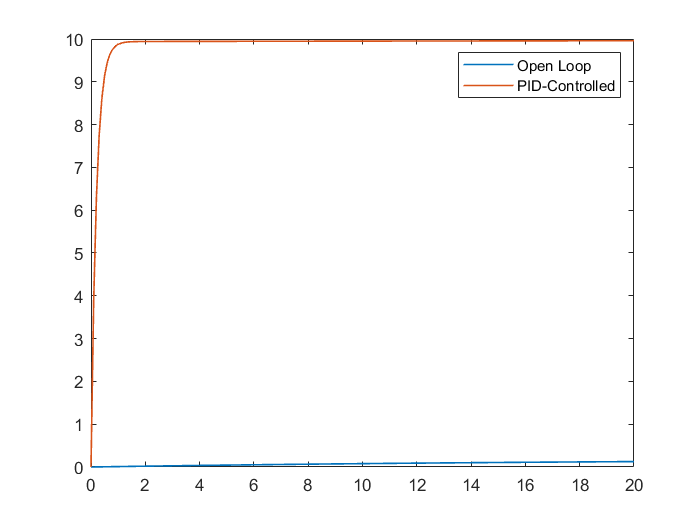

% Lets assume a value of Kp and Kd
Kp =5000; Kd = 1; Ki =100;
ConPID = pid(Kp,Ki,Kd); % The pid command can be used to design the PID conroller
PID = feedback(ConPID*P_cruise,1);% feedback command places the controller structure.
%-- Simulate the closed loop system
[Yc_pid,t,Xc_pid]=step(PI*Ref,t); % Simulating closed loop response
%--- 
figure;
plot(t,Y_ol,'LineWidth',1); hold on;plot(t,Yc_pid,'LineWidth',1);
legend('Open Loop','PID-Controlled'); 

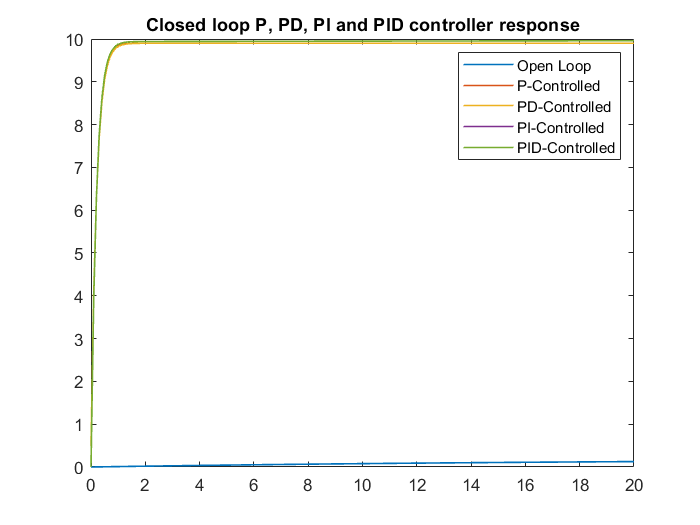

%----- Plot the response for P, PD and PI controller
figure;
plot(t,Y_ol,'LineWidth',1); hold on; plot(t,Yc_p,'LineWidth',1);
plot(t,Yc_pd,'LineWidth',1);plot(t,Yc_pi,'LineWidth',1);
plot(t,Yc_pid,'LineWidth',1);
legend('Open Loop','P-Controlled','PD-Controlled','PI-Controlled','PID-Controlled'); 
title('Closed loop P, PD, PI and PID controller response');